clear;


new_loadshedding = readtable("Loadshedding schedulec 1 June 2018 until Aug 2023 (2).xlsx")

new_loadshedding = 15632×5 table
       Date         Time             Stage                       Area                 DurationMin
    ___________    _______    ___________________    _____________________________    ___________

    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Clvly 66 - MS 1 and 2'    }      {'37' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Mznbg 66 - MS 1 and 2'    }      {'37' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Mznbg 66 - Stnbg 1 and 2' }      {'38' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Clvly 66 - Snvly 1 and 2' }      {'39' }  
    14-Jun-2018    0.76667    {'Stage 1, Area 9'}    {'Athln 132 - Bofrs 1 and 2'}      {'99' }  
    14-Jun-2018    0.76667    {'Stage 1, Area 9'}    {'Eppng 132 - Bnthl 1 and 2'}      {'100'}  
    14-Jun-2


startDate = datetime('2022-01-01 00:00:00', 'Format', 'yyyy-MM-dd HH:mm:ss');
endDate = datetime('2022-12-31 23:59:00', 'Format', 'yyyy-MM-dd HH:mm:ss');
allDateTimes = startDate:hours(1):endDate;

Area15Idx = (new_loadshedding.Area == "Area 15");

loadShedding = new_loadshedding(Area15Idx,:);
loadShedding.eventDateTimes = datetime(loadShedding.Date, 'InputFormat', 'dd-MMM-yyyy') + days(loadShedding.Time)

loadShedding = 860×6 table
       Date          Time                  Stage                    Area        DurationMin    eventDateTimes
    ___________    ________    ______________________________    ___________    ___________    ______________

    17-Mar-2019         0.5    {'Stage 4: Area 7, 11 and 15'}    {'Area 15'}      {'149'}       17-Mar-2019  
    18-Mar-2019     0.16667    {'Stage 2: Area 7 and 15'    }    {'Area 15'}      {'135'}       18-Mar-2019  
    18-Mar-2019         0.5    {'Stage 4: Area 7, 11 and 15'}    {'Area 15'}      {'144'}       18-Mar-2019  
    19-Mar-2019         0.5    {'Stage 4, area 15'          }    {'Area 15'}      {'149'}       19-Mar-2019  
    19-Mar-2019     0.83333    {'Stage 4, area 15'          }    {'Area 15'}      {'144'}       19-Mar-2019 



eventFlag = zeros(length(allDateTimes),1);
allDateTimes = table(allDateTimes',eventFlag,VariableNames=["date","LoadShedding"]);
allDateTimes.Time = hour(allDateTimes.date)/24

allDateTimes = 8760×3 table
           date            LoadShedding      Time  
    ___________________    ____________    ________

    2022-01-01 00:00:00         0                 0
    2022-01-01 01:00:00         0          0.041667
    2022-01-01 02:00:00         0          0.083333
    2022-01-01 03:00:00         0             0.125
    2022-01-01 04:00:00         0           0.16667
    2022-01-01 05:00:00         0           0.20833
    2022-01-01 06:00:00         0              0.25
    2022-01-01 07:00:00         0           0.29167
    2022-01-01 08:00:00         0           0.33333
    2022-01-01 09:00:00         0             0.375
    2022-01-01 10:00:00         0           0.41667
    2022-01-01 11:00:00         0           0.45833
    2022-01-01 12:00:00         0               0.5
    2022-01-01 13:00:00         0           0.54167
    2022-01-01 14:00:00         0    

allDateTimes = outerjoin(allDateTimes,loadShedding,"Type","left","LeftKeys",["date","Time"],"RightKeys",["eventDateTimes","Time"])

allDateTimes = 8760×9 table
           date            LoadShedding    Time_allDateTimes    Date    Time_loadShedding      Stage          Area       DurationMin    eventDateTimes
    ___________________    ____________    _________________    ____    _________________    __________    __________    ___________    ______________

    2022-01-01 00:00:00         0                     0         NaT            NaN           {0×0 char}    {0×0 char}    {0×0 char}          NaT      
    2022-01-01 01:00:00         0              0.041667         NaT            NaN           {0×0 char}    {0×0 char}    {0×0 char}          NaT      
    2022-01-01 02:00:00         0              0.083333      


for i = 1:size(allDateTimes.date(:))
    if ismember('Area 15',allDateTimes.Area(i))
        duration = floor(str2num(cell2mat(allDateTimes.DurationMin(i)))/60);
        for j = 0:duration
            allDateTimes.LoadShedding(i+j) =1;
        end
    end
end

summary(allDateTimes)

Variables:

    date: 8760×1 datetime

        Values:

            Min       2022-01-01 00:00:00
            Median    2022-07-02 11:30:00
            Max       2022-12-31 23:00:00

    LoadShedding: 8760×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Time_allDateTimes: 8760×1 double

        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    Date: 8760×1 datetime

        Properties:
            Description:  Date
        Values:

            Min             03-Feb-2022  
            Median          28-Oct-2022  
            Max             30-Dec-2022  
            NumMissing      8555         

    Time_loadShedding: 8760×1 double

        Properties:
            Description:  Time
        Values:

            Min             0        
            Median          0.4

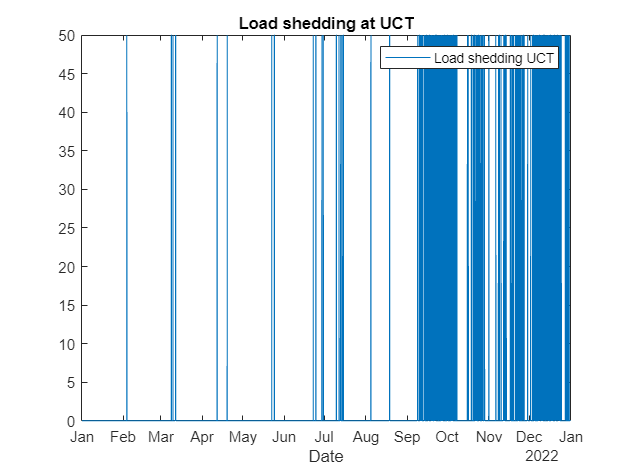


loadSheddinIdx = allDateTimes.LoadShedding == 1;

plot(allDateTimes.date,loadSheddinIdx*50)

legend("Load shedding UCT");
title("Load shedding at UCT")
xlabel("Date")

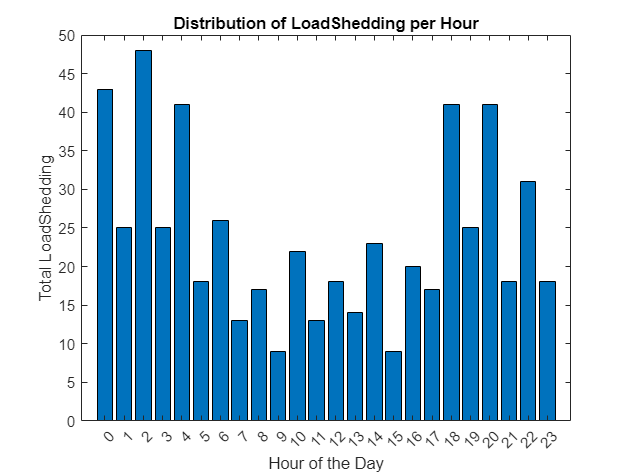



hours = hour(allDateTimes.date);

for h = 0:23
    totalLoadSheddingPerHour(h+1) = sum(allDateTimes.LoadShedding(hours == h));
end
figure;
bar(0:23, totalLoadSheddingPerHour);
xlabel('Hour of the Day');
ylabel('Total LoadShedding');
title('Distribution of LoadShedding per Hour');
xticks(0:23);

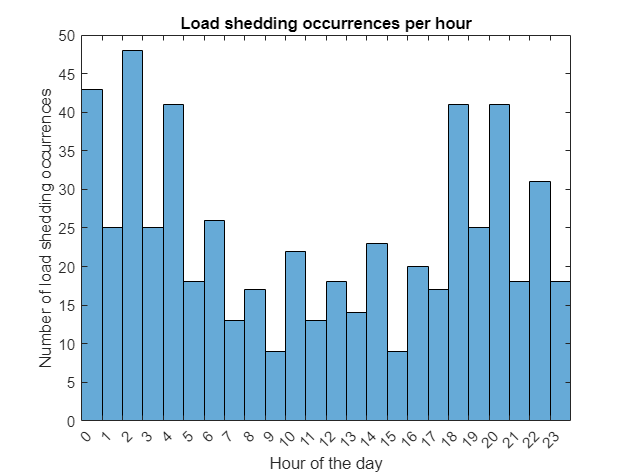



sheddingHours = hours(allDateTimes.LoadShedding == 1);

figure;
histogram(sheddingHours, 0:24); % 0:24 will ensure bins for each hour
xlabel('Hour of the day');
ylabel('Number of load shedding occurrences');
title('Load shedding occurrences per hour');
xticks(0:23);
xlim([0,24])


%writetable(allDateTimes(:,'LoadShedding'), "loadShedding2018_2023.csv");